# Lecture 4 notes

Welcome back! In the [previous lecture](https://martinnilsson.netlify.app/post/eeg-analysis-with-matlab-lecture-3/), we covered the following:

- Scripts are used to automatically perform a series of commands on the input you specify (such as your EEG data). A script can be anywhere between a few lines of code to many thousands of lines long.

- You can write scripts in either the Live Script Editor or the Script Editor. Whichever you use, try to make your code as easy to understand as possible by using comments, spaces, sections, and so on.

- The control flow is the order in which the code in a script is executed. By default, MATLAB uses sequential control flow. However, sometimes, you want specific commands to be executed based on whether a condition is met and other commands to be executed if not, which is called conditional control flow. Finally, loop control flow is used when you wish to repeat a set of commands until some condition is met.

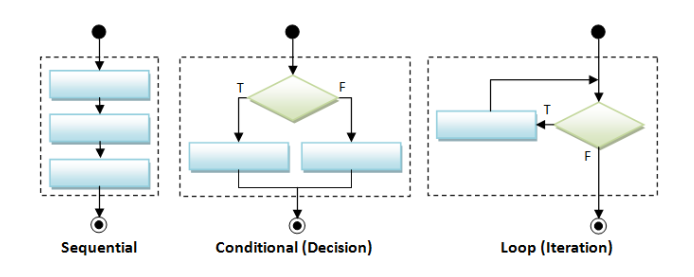

The image shows different possibilities to control the execution of commands in MATLAB and is taken from [this link](https://www3.ntu.edu.sg/home/ehchua/programming/java/images/Flowchart_FlowControl.png).

- The `if` statement is an example of a conditional statement. We only need the initial `if` statement, but if we have additional conditions, we can add `elseif` and `else`. For example:

myNumber = randi(10); % create random integer between 1 and 10

if myNumber < 4
    disp('The number is small.')
elseif myNumber < 7
    disp('The number is medium.')
else
    disp('The number is large.')
end

disp(['The number is equal to ' num2str(myNumber)])

- Above, we combined the two text strings (or character vectors) `'a is equal to '` and `num2str(a)` into one text string. What would happen if you separated the two strings by a comma instead of just a space (as above)? What if you used neither space nor comma?

## For Loops

The `for` loop is a loop that runs a specified number of times. It lets you execute a sequence of commands as many times as you choose. We may, for example, want to create a `for` loop that preprocesses our data 30 times, one time for every subject in our experiment. If you know how many times you want a loop to run beforehand, you should use a `for` loop.

Here is the general structure of the `for` loop in MATLAB:

Code example:

for i = [1 2 3 4] % loop repeats 4 times
    disp(i) % statement inside the loop
end

The code "inside" the loop is repeated four times in the loop above because our counter, which is called i (for index), takes the values 1, 2, 3, and 4. Note that you do not have to call the counter `i`, but `i` is commonly used.

As we have seen previously, another way of writing the vector `[1 2 3 4]` is with a colon as `1:4`. This is commonly used when writing `for` loops:

% This loop counts up from one to four:
for i = 1:4
    disp(i)
end

The code above does the same thing. First, `i = 1`, upon which we disp `1`. Then, `i = 2,` and we display `2`. This continues until the last value (`i = 4)`, and then the loop ends.

Below are some more examples with different index values.

for i = 1:8 % You can also write for(i=1:8) if you prefer
    disp(i) % display i
end

for i = 1:2:9 % from 1 to 9, in steps of 2
    disp(2*i) % double the value of i and display it
end

for i = [1 5 7 3 2]
    disp(i) % display i
end

- How would you create a `for` loop that counts from 20 to 100 in steps of 4?

We are, of course, interested in more than just counting when we use loops. Below is an example where we use indexing to create a new vector ***x ***inside the loop:

for i = 1:6
    x(i) = i
end

Because the counter `i` changes with every iteration (repetition) of the loop, we are indexing different elements of the vector ***x *** and replacing them on every iteration. Basically, what is happening inside the loop looks something like this:

x(1) = 1 % first iteration of the loop
x(2) = 2
x(3) = 3
x(4) = 4
x(5) = 5
x(6) = 6 % last iteration of the loop

Above, we created the variable ***x*** inside the loop. We often already have an existing variable, or we create one specifically for the loop. We could use the `zeros` function, which creates a matrix of zeros (remember that you can type `help` `zeros` in the Command Window or search the documentation if needed). Below, I first create a matrix of zeros called ***myVector***. I then replace the values of ***myVector*** with `i`, which goes from 1 to 10:

myVector = zeros(1,10); % create 1x10 vector of zeros
for i = 1:10
    myVector(i) = i % fill the vector (replacing the 0s).
end

Now, let us try a slightly more technical loop:

clear;clc;
numSubjects = 30; % Number of subjects
myMatrix = zeros(1, numSubjects) % Use numSubjects to create a 1x30 vector of zeros
for subi = 1:numSubjects % from 1 to 30
    myMatrix(subi) = subi*subi % fill the vector with i^2
end

In the code above, we first declare a variable called numSubjects, and assign it the value 30. Next, a vector of zeros is created similarly to the previous code, except now I am using the **numSubjects** variable instead of simply writing out 30. The same thing goes for the loop counter, which is now called **subi** and counts from 1 to 30. Finally, this time we replace the values of myMatrix with i*i. Try changing the value of numSubjects, leaving everything else similar, and see if the code still works.

In this example, I have a 5x5 matrix called ***myMatrix***. For every row, I would like to calculate the mean of columns 1 and 2. I would then like to add the resulting vector of means to ***myMatrix*** as a new column. One example of how to do this would be the following:

myMatrix = randi(10,5,5) % 5x5 matrix of random integers between 1 and 10

for i=1:5 % go through every row
    myMatrix(i,6) = mean(myMatrix(i,[1 2])); % calculate the mean of row i, columns [1 2],
end                                          % and assign it to row i, column 6.
disp(myMatrix)

Notice that, even though ***myMatrix*** only has 5 columns before the loop, it is possible to add values to a 6th column using indexing. Feel free to try it out yourself without any loops to complicate things.

Another possible way to solve the issue above would be to create a vector of means with the loop and then combine that vector with myMatrix after the loop has finished. Depending on how you create your vector, you might also need to transpose your vector to make it fit with ***myMatrix***.

## While Loops

While loops do not repeat a specific amount of time, but instead the loop continues until some condition, such as a threshold, is reached. 

Here is the general structure of the `while` loop in MATLAB:

Here is our first example of a `while` loop:

myNumber = 2;

while myNumber < 1000
    myNumber = myNumber*2;
end

myNumber

We start by assigning the value 2 to ***myNumber***. The loop above repeats itself while the condition `myNumber < 1000` is true. What we are doing inside the loop is that we are doubling ***myNumber***, until `myNumber < 1000` is false. Relational and logical operators (see [lecture 2](https://martinnilsson.netlify.app/post/eeg-analysis-with-matlab/)) are very useful for creating these types of loops. 

*A word of caution*: when using while loops, you may make a mistake, and the loop will continue forever, i.e. you have accidentally created an infinite loop. Remember that if that happens you can use the Ctrl + C (command + C on Mac) shortcut to abort. Here is an example of an infinite loop:

a=1
while a < 1000
    a = a -1
end

The loop goes infinite becuase the condition a < 1000 is always true (becuase a becomes smaller and smaller).

Below is an example with a different relational operator. Can you figure out what this loop does before running it yourself?

B = 1024
A = 2

while A ~= B
    A = A + 2
end


When using while loops, we likely want to know how many times the loop actually repeats itself. We could solve this by including a variable that updates itself every time the loop repeats. This example also illustrates that you can include more than one command within the loop. The same is true for `for` loops:

myNumber = 2; % set myNumber to 2
loopcount = 0; % set loopcount to 0
while myNumber < 1000 % run the code below for as long as myNumber is less than 1000
    myNumber = myNumber*2; % double the value of myNumber
    loopcount = loopcount + 1; % increase loopcount by 1
end
myNumber
loopcount

- After running the loop, myNumber is larger than 1000. Why is it not less than 1000?

- How many times did the loop iterate?

You can also include conditionals (or more loops) inside loops. Here is an example:

myNumber = 2 % start with 2
while myNumber < 1000 % Perform everything inside the loop while myNumber is < 1000
    if myNumber < 500 % if myNumber is < 500
        myNumber = myNumber*2 % double myNumber
    else % else if myNumber is not less than 500 (i.e. above 500 but under 1000)
        myNumber = myNumber + 20 % add 20 to myNumber
    end % end if statement
end % end while loop

**Summary**

- Loops are ubiquitous within programming. The for loop is a loop that runs a specified number of times, and it, therefore, makes sense to use it when you know how many times you want to repeat something (for example, one time for every subject/trial). The while loop is a loop that repeats itself until some condition is met.

- You can create loops within loops (nested loops), conditionals within loops, loops within conditionals, and so on. However, if you can solve a problem without using a loop (for example, using various matrix operations), you should consider doing so, as loops are generally slower.